if use_nlms
    y_fxnlms = y(end, :);
    e_fxnlms = e(end, :);
    w_fxnlms = w(:, end);
else
    y_lms = y(end, :);
    e_lms = e(end, :);
    w_lms = w(:, end);
end


Unrecognized function or variable 'u'.

% figure
% hold on
% plot(d)
% hold on
% plot(y_lms)
% legend('true reverb', 'predicted')

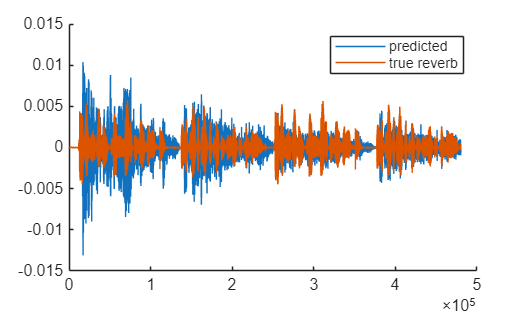

figure
hold on
plot(y_nlms)
hold on
plot(target)
legend('predicted', 'true reverb')

[y_source, fs] = audioread("arthur_clip_48k.wav");

nlms_out = u(1:length(y_source));
cancel = [nlms_out, y_source];

no_cancel = [zeros(size(y_source)), y_source];

audiowrite("no_cancel.wav", no_cancel, fs);
audiowrite("cancel.wav", cancel, fs);

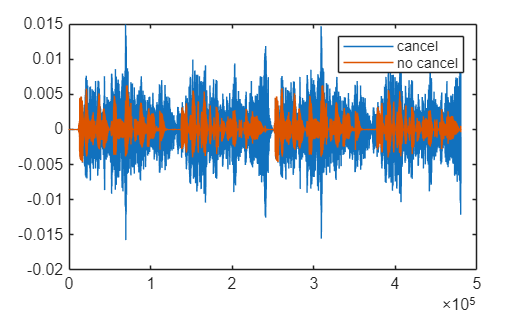

[mics_cancel, fs] = audioread("double_mics_cancel.wav");
[mics_no_cancel, fs] = audioread("double_mics_no_cancel.wav");

reverb_cancel = mics_cancel(:, 1);
reverb_no_cancel = mics_no_cancel(:, 1);

figure
plot(reverb_cancel)
hold on
plot(reverb_no_cancel)
legend('cancel', 'no cancel')